# Specify Repeated Conversion Specifiers and Collect Numeric Data

Load the data file `grades.txt` for this example and preview its contents in a text editor. A screen shot is shown below. Notice the file contains repeated delimiters.

filename = 'grades.txt';

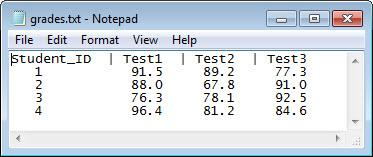

Read the column headers using the format `'%s'` four times.

fileID = fopen(filename);
formatSpec = '%s';
N = 4;
C_text = textscan(fileID,formatSpec,N,'Delimiter','|');

Read the numeric data in the file.

C_data0 = textscan(fileID,'%d %f %f %f')

The default value for `CollectOutput` is `0` (`false`), so `textscan` returns each column of the numeric data in a separate array.

Set the file position indicator to the beginning of the file.

frewind(fileID);

Reread the file and set CollectOutput to 1 (true) to collect the consecutive columns of the same class into a single array. You can use the `repmat` function to indicate that the `%f` conversion specifier should appear three times. This technique is useful when a format repeats many times.

C_text = textscan(fileID,'%s',N,'Delimiter','|');
C_data1 = textscan(fileID,['%d',repmat('%f',[1,3])],'CollectOutput',1)

The test scores, which are all double, are collected into a single 4-by-3 array.

Close the file.

fclose(fileID);

*Copyright 2012 The MathWorks, Inc.*